clear all;
clf;

## Quadcopter parameters and physical constants

global g quad_mass_kg black_mass_kg white_mass_kg Fit_thrust Fit_power theta_deg dyn_friction_coeff cart_height_m thrust_centerline_distance_m k1_m k2_m k3_m k4_m

sim_setup.g = 9.81;
sim_setup.quad_mass_kg = 2*29.088E-3 + 2*0.101 + 2*0.051 + 0.15; % mass of arm structures + ESC + motors !!(NEEDS TO CHANGE, PROVIDED BY STRUCTURES)!!
sim_setup.black_mass_kg = 0.06924; % mass of black mounting plate
sim_setup.white_mass_kg = 0.08076; % mass of white plates (plates interacting with lidar sensor)

thrust_data_kgf_W = xlsread('motorspecs.xlsx');
sim_setup.Fit_thrust = fit(thrust_data_kgf_W(:,1), thrust_data_kgf_W(:,2), 'smoothingspline');
sim_setup.Fit_power = fit(thrust_data_kgf_W(:,1), thrust_data_kgf_W(:,3), 'smoothingspline');

sim_setup.k1_m = 0.01; % CoG of the quadcopter except the cable
sim_setup.k2_m = 0.024 + 0.05/4; % Attachment point of the cable
sim_setup.k3_m = 0.024; % CoG of black mounting plate
sim_setup.k4_m = 0.024 + 0.05/2; % CoG of white plates (plates interacting with lidar sensor)

sim_setup.theta_deg = 0; % thrust tilt angle !!(NEEDS TO CHANGE, PROVIDED BY STRUCTURES)!!
sim_setup.dyn_friction_coeff = 0.14;
sim_setup.cart_height_m = 0.2104

sim_setup = struct with fields:
                     g: 9.8100
          quad_mass_kg: 0.5122
         black_mass_kg: 0.0692
         white_mass_kg: 0.0808
            Fit_thrust: [1×1 cfit]
             Fit_power: [1×1 cfit]
                  k1_m: 0.0100
                  k2_m: 0.0365
                  k3_m: 0.0240
                  k4_m: 0.0490
             theta_deg: 0
    dyn_friction_coeff: 0.1400
         cart_height_m: 0.2104


sim_setup.thrust_centerline_distance_m = 0.01; % TODO: CHANGE!

max_y_m = 1.44;
motor_esc_delay = 0.3031;

## LQR Setup

a = [0, -0.19*sim_setup.g; 1, 0];
b = [2*9.81; 0]; % Use actual value
M = [sim_setup.quad_mass_kg, 0; 0, 1]; % Test if including cable weight in some sort helps
A = M^-1*a;
B = M^-1*b;

Q = [0, 0; 0, 1];%[0, 0; 0, 1];%
R = 0.01 % Energy consumption weighting

R = 1

K = lqr(A, B, Q, R)

K =     0.2179    0.9095


if false
    p = optimizableVariable('p', [0, 1.5]);
    i = optimizableVariable('i', [0, 1]);
    d = optimizableVariable('d', [0, 0.8]);
    result = bayesopt(@manyRuns, [p, i, d], "IsObjectiveDeterministic",false, 'MaxObjectiveEvaluations', 100) 
end

## Controller and path

% Waypoints as timeseries (format is (y_location, time))
waypoints = timeseries([0, 10, 100, 15, 48, 14]', [0, 5, 8, 13, 15, 19]);
load('samplemission_edited.mat')
%assert(checkTrack(waypoints), 'Track is impossible to do due to acceleration limits');


%controller = ControlSystem([1.49600751362063	1.49423390218823	0.260291881899267], waypoints)
%controller = ControlSystem([0.8, 0.6, 0.3], waypoints)
controller = LQRController(K, waypoints);

if false
    a = [1.2, 0.6, 0.3]
    a = [1.1865, 0.99865, 0.26707]
    gains.p = a(1);
    gains.i = a(2);
    gains.d = a(3);
    gains.K = K;
    manyRuns(gains)
end

## Simulation parameters

T_max = max(waypoints.Time);
dt = 5E-4;

% Initial position and acceleration
y0 = 0;
v0 = 0;

sim_setup.thrust_buffer = zeros(1, round(motor_esc_delay/dt));

## Simulation loop

y = y0;
v = v0;

t_arr = 0:dt:T_max;

logs.t = t_arr;
logs.y = zeros(numel(t_arr), 1);
logs.v = zeros(numel(t_arr), 1);
logs.thrust = zeros(numel(t_arr), 1);
logs.power = zeros(numel(t_arr), 1);

for t_idx = 1:numel(t_arr)
    t = t_arr(t_idx);
    
    thrust = controller.calculate(y, t);
    accel = accelerationFunction(thrust, y, v, sim_setup);
    power = powerFunction(thrust, sim_setup);
    
    y = y + v*dt;
    v = v + accel*dt;
    
    % Make sure to not fall through the floor
    if y <= 0
        y = 0;
        v = max(0, v); % make sure v is not negative
    end
    
    if y >= max_y_m
        y = max_y_m;
        v = min(0, v); % make sure v is only negative
    end
        
    logs.y(t_idx) = y;
    logs.v(t_idx) = v;
    logs.thrust(t_idx) = thrust;
    logs.power(t_idx) = power;
end

## Plotting

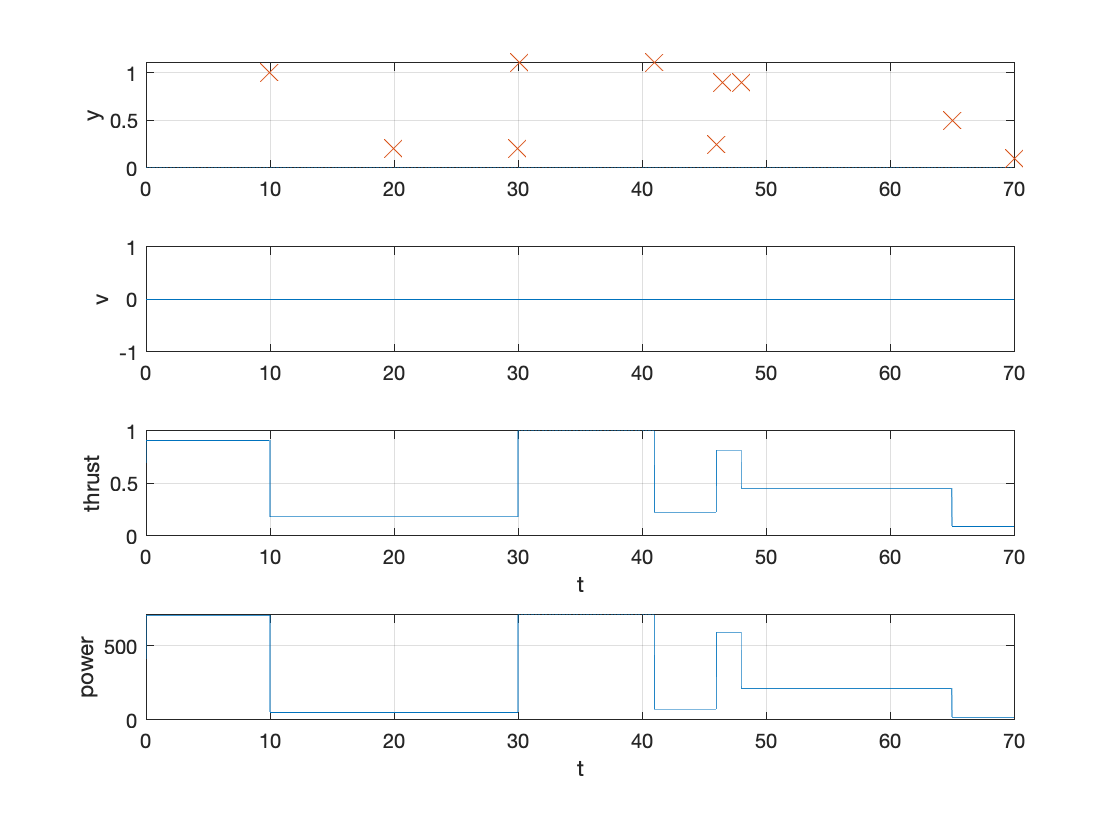

figure;

subplot(4, 1, 1);
plot(logs.t, logs.y);
grid on;
hold on;
scatter(waypoints.Time, waypoints.Data, 150, 'x');
ylabel('y')
hold off;

subplot(4, 1, 2);
plot(logs.t, logs.v);
grid on;
ylabel('v')

subplot(4, 1, 3);
plot(logs.t, logs.thrust);
grid on;
ylabel('thrust')
xlabel('t')

subplot(4, 1, 4);
plot(logs.t, logs.power);
grid on;
ylabel('power')
xlabel('t')


accuracy = calcAccuracy(logs, waypoints)

accuracy = 0.6584

energy_total = trapz(logs.t, logs.power)

energy_total = 2.1140e+04

n_pts = 50;
R_range = logspace(-4, -0.5, n_pts);
Q_temp = [0, 0; 0, 1];

energy = zeros(1, n_pts);
accuracy = zeros(1, n_pts);
parfor i = 1:numel(R_range)
    disp(i);
    r_sample = R_range(i);
    K_temp = lqr(A, B, Q_temp, r_sample);
    [tmp1, tmp2] = oneRun(K_temp, sim_setup);
    
    accuracy(i) = tmp1;
    energy(i) = tmp2;
end

     1

     2

     3

     4

     5

     6

     7

     8



semilogx(R_range, accuracy/mean(accuracy));
hold on;
semilogx(R_range, energy/mean(energy));
legend('normalised error rms', 'normalised energy consumed')
xlim([10^-4, 10^-0.5])
grid
hold off;



function accel = accelerationFunction(thrust, y, v, ss) % Calculates acceleration in kgms^-2, +ve up
% TODO: Add weight of the cable track as a function of y
    
    if size(ss.thrust_buffer, 2) == 0
        thrust_actual = thrust;
    else
        thrust_actual = ss.thrust_buffer(end);
        ss.thrust_buffer = circshift(ss.thrust_buffer, 1);
        ss.thrust_buffer(1) = thrust;
    end
    
    thrust_term = ss.Fit_thrust(thrust_actual*100)*ss.g*cosd(ss.theta_deg)*2;
    cable_mass_kg = 0.19*(y + 0.5648);
    total_mass_kg = ss.quad_mass_kg + cable_mass_kg + ss.black_mass_kg + ss.white_mass_kg;
    grav_term = -(ss.quad_mass_kg + cable_mass_kg + ss.black_mass_kg + ss.white_mass_kg)*ss.g;
    total_weight_moment = -ss.quad_mass_kg*ss.g*ss.k1_m - cable_mass_kg*ss.g*ss.k2_m - ss.black_mass_kg*ss.g*ss.k3_m - ss.white_mass_kg*ss.g*ss.k4_m;
    
    if v == 0
        % TODO: Static friciton model
        resultant = thrust_term + grav_term;
        static_friction = 0.13*ss.g;
        if abs(resultant) < static_friction
            accel = 0;
            return;
        else
            friction_term = -sign(resultant)*static_friction;
        end
    else
        ff1 = abs(ss.dyn_friction_coeff*(thrust_term*ss.thrust_centerline_distance_m*cosd(ss.theta_deg) + total_weight_moment)/ss.cart_height_m);
        ff2 = abs(ss.dyn_friction_coeff*(thrust_term*(ss.cart_height_m*tand(ss.theta_deg) - ss.thrust_centerline_distance_m)*cosd(ss.theta_deg) - total_weight_moment)/ss.cart_height_m);
        
        
        friction_term = -(ff1 + ff2)*sign(v);       
    end
    accel = (thrust_term + grav_term + friction_term) / total_mass_kg;
end

function rms_accuracy = calcAccuracy(logs, waypoints)
    [~, time_indices] = min(abs(logs.t - waypoints.Time), [], 2);
    prev_idx = 1;
    err = 0;
    
    for idx_num = 1:numel(time_indices)
        idx = time_indices(idx_num);
        err = err + sum((logs.y(prev_idx:idx) - waypoints.Data(idx_num)).^2);
        prev_idx = idx;
    end
    
    %accuracies = waypoints.Data - logs.y(time_indices)
    %accuracy = logs.y - waypoints.Data
    %rms_accuracy = sqrt(mean(accuracies.^2));
    rms_accuracy = sqrt(err/numel(logs.t));
end

function randomWaypoints = randomTrack()
    n = randi([5, 15]);
    rand_height = @()(0-1.44).*rand() + 1.44;
    times = zeros(1, n);
    heights = zeros(1, n);
    
    times(1) = randi([0, 4]);
    heights(1) = rand_height();
    
    for idx = 2:n
        times(idx) = times(idx - 1) + randi([1, 5]);
        heights(idx) = rand_height();
    end
    
    randomWaypoints = timeseries(heights, times);
end

function power = powerFunction(thrust, ss)
    power = ss.Fit_power(thrust*100)*2;
end

function [accuracy, energy] = manyRuns(gains)

    n = 12;
    accs = zeros(1, n);
    energies = zeros(1, n);
    for i = 1:n
        [tmp1, tmp2] = oneRun(gains);
        accs(i) = tmp1;
        energies(i) = tmp2;
    end
    
    accuracy = mean(accs);
    energy = mean(energies);
end

function [accuracy, energy] = oneRun(gains, ss)
    waypoints = randomTrack();
    waypoints = timeseries([1, 0.2, 0.2, 1.1, 1.1, 0.25, 0.9, 0.9, 0.5, 0.1], [10, 20, 30, 30.1, 41, 46, 46.5, 48, 65, 70]);
    if true
        controller = LQRController(gains, waypoints);
    else
        controller = ControlSystem([gains.p, gains.i, gains.d], waypoints);
    end
    
    T_max = max(waypoints.Time);
    dt = 5E-4;
    max_y_m = 1.44;
    motor_esc_delay = 0;
    % Initial position and acceleration
    y0 = 0;
    v0 = 0;
    
    y = y0;
    v = v0;
    
    ss.thrust_buffer = zeros(1, round(motor_esc_delay/dt));
    
    t_arr = 0:dt:T_max;
    
    logs.t = t_arr;
    logs.y = zeros(numel(t_arr), 1);
    logs.v = zeros(numel(t_arr), 1);
    logs.thrust = zeros(numel(t_arr), 1);
    logs.power = zeros(numel(t_arr), 1);
    
    for t_idx = 1:numel(t_arr)
        t = t_arr(t_idx);
        
        thrust = controller.calculate(y, t);
        accel = accelerationFunction(thrust, y, v, ss);
        
        y = y + v*dt;
        v = v + accel*dt;
        
        % Make sure to not fall through the floor
        if y <= 0
            y = 0;
            v = max(0, v); % make sure v is not negative
        end
        
        if y >= max_y_m
            y = max_y_m;
            v = min(0, v); % make sure v is only negative
        end
        
        
        logs.y(t_idx) = y;
        logs.v(t_idx) = v;
        logs.thrust(t_idx) = thrust;
        logs.power(t_idx) = powerFunction(thrust, ss);
    end
    
    accuracy = calcAccuracy(logs, waypoints);
    energy = trapz(logs.t, logs.power);
end